## **Name: Md Toufique Hasan**

## **Student Number: 151129267**

## **Exercise date: 24/11/2022**

## **Data Mining Exercise: 3**

### ***Answer: 1***

%% Read File
file = readtable(['D:\TUNI\Courses\Period-2\DATA.ML.340 [Data Mining]\' ...
    'Weekly exercises 3\bloodp.xlsx']);

%% Replace zero values using mean value
file.sbp(find(file.sbp == 0)) = mean(file.sbp, 'omitnan');
file.dbp(find(file.dbp == 0)) = mean(file.dbp, 'omitnan');

%% Replace missing values using the mean
file.sbp(isnan(file.sbp)) = mean(file.sbp, 'omitnan');
file.dbp(isnan(file.dbp)) = mean(file.dbp, 'omitnan');

mean(file.sbp)

ans = 144.9076

mean(file.dbp)

ans = 82.3162

%% Correct the erroneous values
isnan(file.sbp);
isnan(file.dbp);

%% sbp must be greater than 80. Values below must be multiplied by 10.
i = (file.sbp < 10);
file.sbp(i) = 10* file.sbp(i);
Deletesbp = file.sbp >= 10 & file.sbp <= 80;
file(Deletesbp,:) = [];

%% dbp must be over 40. Values below must be multiplied by 10
i = (file.dbp < 10);
file.dbp(i) = 10* file.dbp(i);

Deletedbp = file.dbp >= 10 & file.dbp <= 40;
file(Deletedbp,:) = [];

%% sbp over 300 or dbp over 160 are impossible: remove
Deletesbp = file.sbp >300;
file(Deletesbp,:) = [];

Deletedbp = file.dbp >160;
file(Deletedbp,:) = [];

### ***Answer: 2***

%% First column is filled with ones
OneCol = ones(length(file.sbp),1);
y = file.dbp;
X = [OneCol,file.sbp];

%% Coefficients for model
bin_cor = (transpose(X)*X) \ transpose(X)*(y)

bin_cor =    38.4213
    0.3214


%% Matlab function regress() that is normally used in linear regression
bin_cor = regress(y,X)

bin_cor =    38.4213
    0.3214


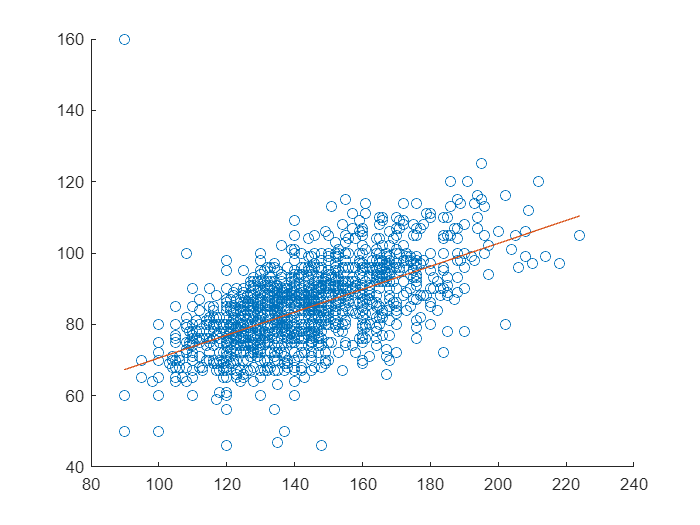

%% Linear regression model for prediction
LM = bin_cor(1) + bin_cor(2)*X(:,2);

%% Plot
scatter(file.sbp, file.dbp)
hold on
plot(X(:,2),LM)

## ***Answer: 3***

%% Refrerence document
Fo = [15, 7, 6, 11, 4]

Fo =     15     7     6    11     4


Nw = 500

Nw = 500

%% Two other documents
Fo1 = [1, 4, 3, 3, 6]

Fo1 =      1     4     3     3     6


Nw1 = 200

Nw1 = 200

Fo2 = [20, 1, 5, 16, 9]

Fo2 =     20     1     5    16     9


Nw2 = 210

Nw2 = 210

%% Normalize first the word occurrences with respective word count
NFr = normalize(Fo/Nw, "range")

NFr =     1.0000    0.2727    0.1818    0.6364         0


NFo1 = normalize(Fo1/Nw1, "range")

NFo1 =          0    0.6000    0.4000    0.4000    1.0000


NFo2 = normalize(Fo2/Nw2, "range")

NFo2 =     1.0000         0    0.2105    0.7895    0.4211


%% Cosine distance
Distance1 = 1 - (dot(NFr,NFo1)/sqrt(sumsqr(NFr)*sumsqr(NFo1)))

Distance1 = 0.6920

Distance2 = 1 - (dot(NFr,NFo2)/sqrt(sumsqr(NFr)*sumsqr(NFo2)))

Distance2 = 0.0777

## ***Answer: 4***

%% Load the power consumption data using Import Data
file1 = TetuanCitypowerconsumption;

%% Binarize all variables
file1(:,1) = [];
bin = table2array(file1);
bin_mean = mean(table2array(file1), 'omitnan');
for i = 1:8
lower_index = find(bin(:,i) < bin_mean(i));
upper_index = find(bin(:,i) > bin_mean(i));
bin(lower_index,i) = 0;
bin(upper_index,i) = 1;
end
bin;

%% Samples
s = [0 1 0 0 0 0 0 0]

s =      0     1     0     0     0     0     0     0


sum(isnan(bin)); 

%% Hamming distance
hamming_distance = transpose(pdist2(s, bin, 'hamming'));

%% Minimum hamming distance
min(hamming_distance);

%% Nearest neighbors
nearest_neighbors = find(hamming_distance == 0);
length(nearest_neighbors)

ans = 7015

There are a total of 7015 samples whose hamming distance is zero, which is considered to be their closest distance.

## ***Answer: 5***

% Binary correlation for binarized data
col_00 = sum((bin(:,1)==0) & (bin(:,2)==0))

col_00 = 9249

col_01 = sum((bin(:,1)==0) & (bin(:,2)==1))

col_01 = 17029

col_10 = sum((bin(:,1)==1) & (bin(:,2)==0))

col_10 = 14897

col_11 = sum((bin(:,1)==1) & (bin(:,2)==1))

col_11 = 11241

bin_cor = (col_11*col_00 + col_10*col_01)/(sqrt((col_11+col_10) * (col_01+col_00) * ...

bin_cor = 0.5223

    (col_11+col_01) * (col_10+col_00)))
%% Loop to calculate binary correlation between 1st and other variables
array = [];
for i = 3:8
col_00 = sum((bin(:,1)==0) & (bin(:,i)==0));
col_01 = sum((bin(:,1)==0) & (bin(:,i)==1));
col_10 = sum((bin(:,1)==1) & (bin(:,i)==0));
col_11 = sum((bin(:,1)==1) & (bin(:,i)==1));
bin_cor = (col_11*col_00 + col_10*col_01)/(sqrt((col_11+col_10) * (col_01+col_00) * ...
    (col_11+col_01) * (col_10+col_00)));
array(end+1) = bin_cor
end

array = 0.5685

array =     0.5685    0.5099


array =     0.5685    0.5099    0.4800


array =     0.5685    0.5099    0.4800    0.5378


array =     0.5685    0.5099    0.4800    0.5378    0.5352


array =     0.5685    0.5099    0.4800    0.5378    0.5352    0.5416


## ***Answer: 6***

Cosine distance is not a ‘true’ metric.

First, it doesn’t satisfy the indiscernible condition. The cosine distance of [1,1] and [2,2] is 0, but [1,1] ≠ [2,2]. Moreover, it doesn’t satisfy triangle inequality.